FOPID Control - SP 35 -> 50

clear model;
filename='FOPID_control_SP_50.csv'

filename = 'FOPID_control_SP_50.csv'

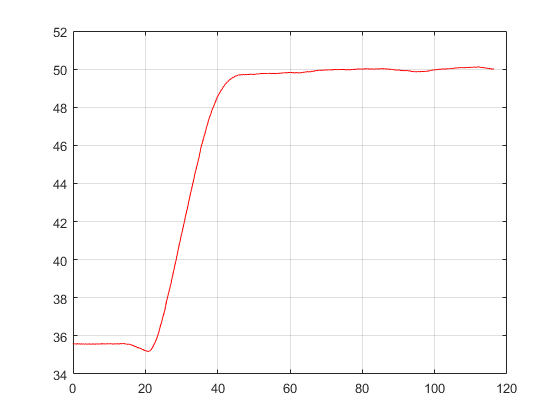

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'D1', 'D2', 'D3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

FOPID_SP_50=model;

plot(FOPID_SP_50.time,FOPID_SP_50.pv,'r');
grid on;

FOPID Control - Resistance Disturbance

clear model;
filename='FOPID_control_D_resistance.csv'

filename = 'FOPID_control_D_resistance.csv'

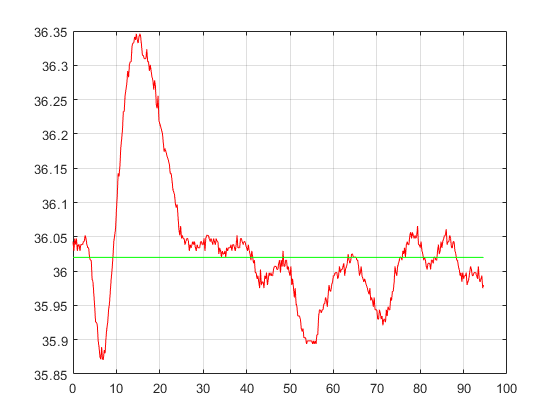

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'D1', 'D2', 'D3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

FOPID_dist_res=model;

plot(FOPID_dist_res.time,FOPID_dist_res.pv,'red');
grid on;
hold on;
plot(FOPID_dist_res.time,FOPID_dist_res.sp,'green');
hold off;

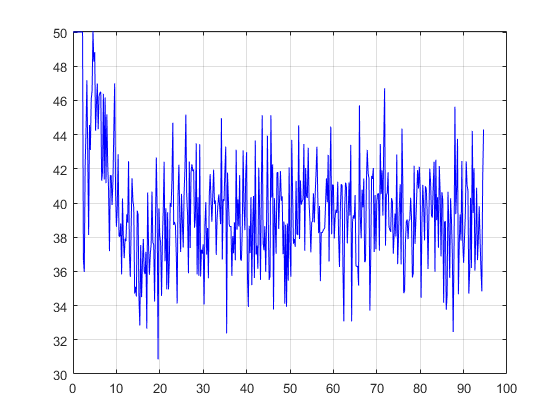

plot(FOPID_dist_res.time,FOPID_dist_res.cv,'blue');
grid on;

FOPID Control - Orifice Disturbance

clear model;
filename='FOPID_control_D_orifice.csv'

filename = 'FOPID_control_D_orifice.csv'

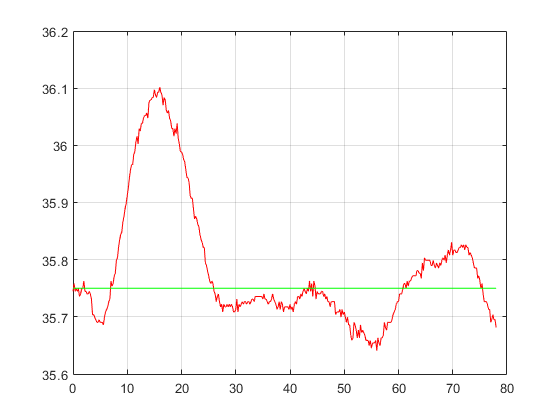

Tp=0.2;
[model.timeUTC model.sp model.pv model.cv model.orifice model.resistance model.ds3] = csvimport(filename, 'columns', {'UTC Time','SP', 'PV', 'CV', 'D1', 'D2', 'D3'});
model.time(1)=0;
for i=2:length(model.timeUTC)
   model.time(i,1)=Tp*(i-1);
end

FOPID_dist_ori=model;

plot(FOPID_dist_ori.time,FOPID_dist_ori.pv,'red');
grid on;
hold on;
plot(FOPID_dist_ori.time,FOPID_dist_ori.sp,'green');
hold off;

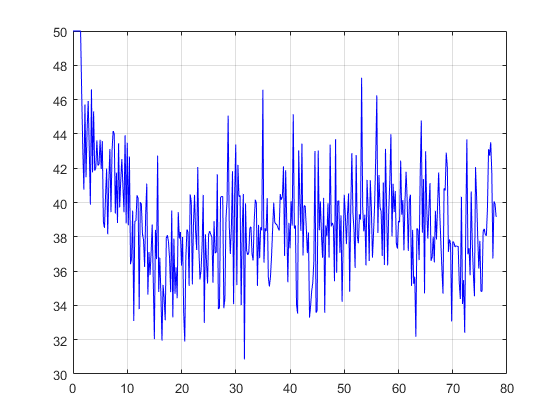

plot(FOPID_dist_ori.time,FOPID_dist_ori.cv,'blue');
grid on;